%INPUTS
sim('inputs.slx');
load('doublet.mat')
time = doublet.Time;
input = [doublet.Data doublet.data];
%input = timetable(input,'SampleRate',50);

### SISO IDentifcation

[A,B,C,D] = linmod('siso_id');

identified_plant = ss(A,B,C,D);
yid = lsim(identified_plant,input,time);

### Original plant

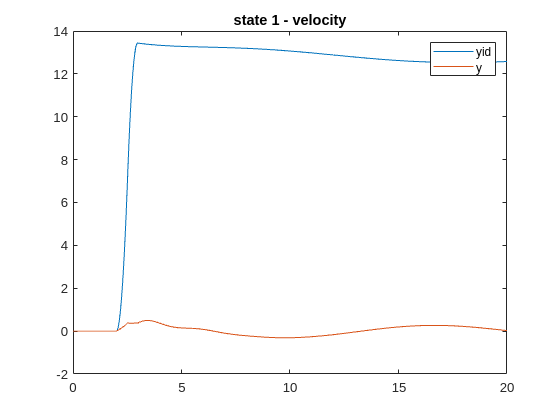

[A,B,C,D] = linmod('nonlinear_model');
original_plant = ss(A,B,C,D);
y = lsim(original_plant,input,time);
figure;
plot(time,yid(:,1))
hold on;
plot(time,y(:,1))
legend('yid','y')
title('state 1 - velocity')

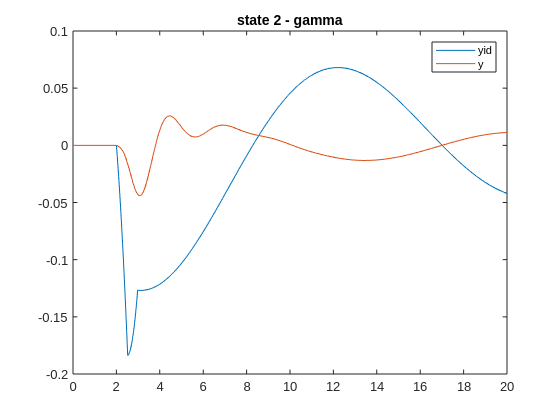

figure;
plot(time,yid(:,2))
hold on;
plot(time,y(:,2))
legend('yid','y')
title('state 2 - gamma')

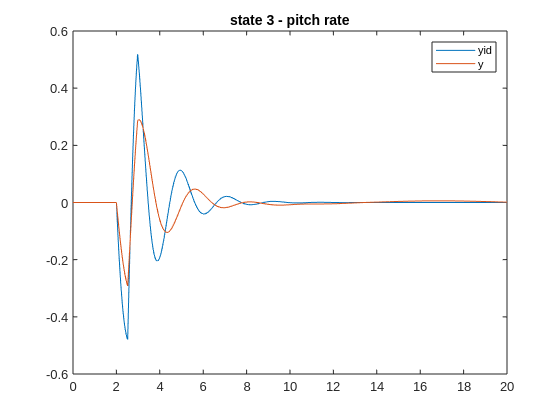

figure;
plot(time,yid(:,3))
hold on;
plot(time,y(:,3))
legend('yid','y')
title('state 3 - pitch rate')

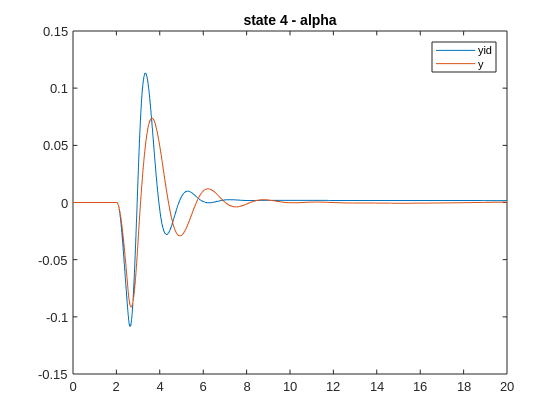

figure;
plot(time,yid(:,4))
hold on;
plot(time,y(:,4))
legend('yid','y')
title('state 4 - alpha')

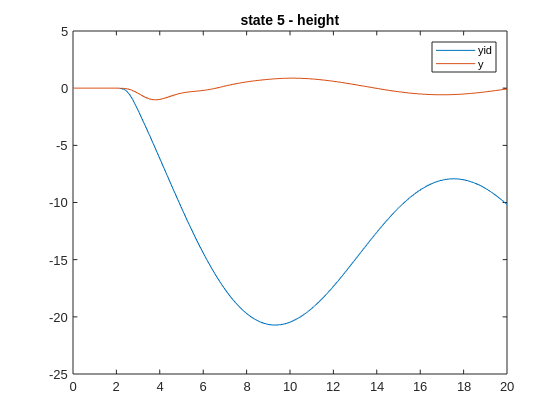

figure;
plot(time,yid(:,5))
hold on;
plot(time,y(:,5))
legend('yid','y')
title('state 5 - height')